# Box Office Grosses

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

movies = readtable("../data/movies.txt", "TextType", "string");
release = readtable("../data/releaseDates.txt", "TextType", "string");
movies = join(movies, release)

movies = 15×4 table
                  Title                  Studio    AdjustedGross    ReleaseDate 
    _________________________________    ______    _____________    ____________

    "101 Dalmatians"                     "Dis."     8.5729e+08      Jan 25, 1961
    "Avatar"                             "Fox"      8.3445e+08      Dec 18, 2009
    "Ben-Hur"                            "MGM"      8.4084e+08      Nov 18, 1959
    "Doctor Zhivago"                     "MGM"      1.0651e+09      Dec 22, 1965
    "E.T.: The Extra-Terrestrial"        "Uni."     1.2171e+09      Jun 11, 1982
    "Gone with the Wind"                 "MGM"      1.7335e+09      Dec 15, 1939
    "Jaws"                               "Uni."     1.0989e+09      Jun 20, 1975
    "Snow White and the Seven Dwarfs"    "Dis."     9.3522e+08      Dec 21, 1937
    "Star Wars"                  

## Task 1

movies = sortrows(movies, "ReleaseDate")

movies = 15×4 table
                  Title                  Studio    AdjustedGross    ReleaseDate 
    _________________________________    ______    _____________    ____________

    "Snow White and the Seven Dwarfs"    "Dis."     9.3522e+08      Dec 21, 1937
    "Gone with the Wind"                 "MGM"      1.7335e+09      Dec 15, 1939
    "The Ten Commandments"               "Par."      1.124e+09       Oct 5, 1956
    "Ben-Hur"                            "MGM"      8.4084e+08      Nov 18, 1959
    "101 Dalmatians"                     "Dis."     8.5729e+08      Jan 25, 1961
    "The Sound of Music"                 "Fox"      1.2219e+09       Mar 2, 1965
    "Doctor Zhivago"                     "MGM"      1.0651e+09      Dec 22, 1965
    "The Exorcist"                       "WB"       9.4894e+08      Dec 26, 1973
    "Jaws"                       

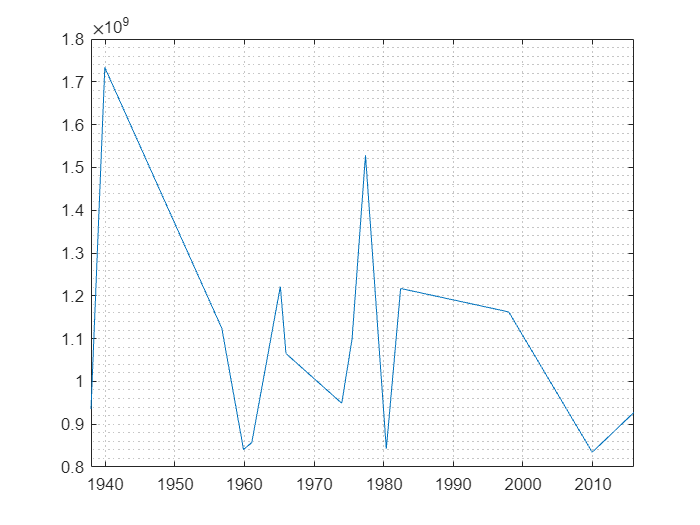

plot(movies.ReleaseDate, movies.AdjustedGross)
grid minor

## Task 2

movies.Studio = categorical(movies.Studio)

movies = 15×4 table
                  Title                  Studio    AdjustedGross    ReleaseDate 
    _________________________________    ______    _____________    ____________

    "Snow White and the Seven Dwarfs"     Dis.      9.3522e+08      Dec 21, 1937
    "Gone with the Wind"                  MGM       1.7335e+09      Dec 15, 1939
    "The Ten Commandments"                Par.       1.124e+09       Oct 5, 1956
    "Ben-Hur"                             MGM       8.4084e+08      Nov 18, 1959
    "101 Dalmatians"                      Dis.      8.5729e+08      Jan 25, 1961
    "The Sound of Music"                  Fox       1.2219e+09       Mar 2, 1965
    "Doctor Zhivago"                      MGM       1.0651e+09      Dec 22, 1965
    "The Exorcist"                        WB        9.4894e+08      Dec 26, 1973
    "Jaws"                       

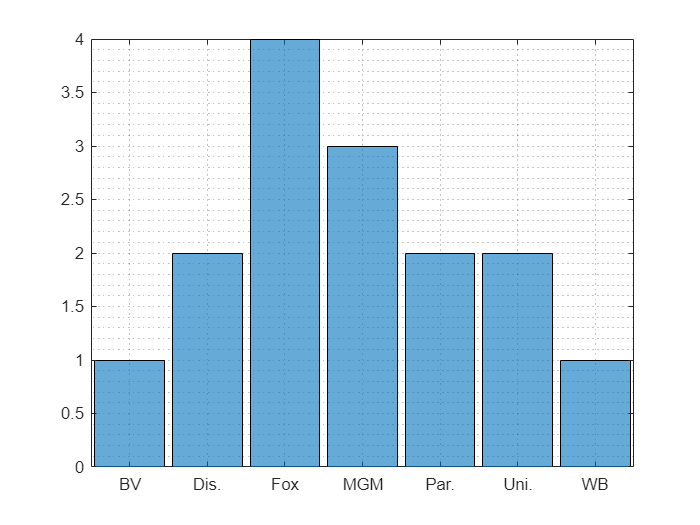

histogram(movies.Studio)
grid minor

## Task 3

mgmIdx = movies.Studio == "MGM"

mgmIdx = 15×1 logical array
   0
   1
   0
   1
   0
   0
   1
   0
   0
   0


mgmMovies = movies.Title(mgmIdx)

mgmMovies = 3×1 string array
    "Gone with the Wind"
    "Ben-Hur"
    "Doctor Zhivago"


mgmARD = mean(movies.ReleaseDate(mgmIdx));